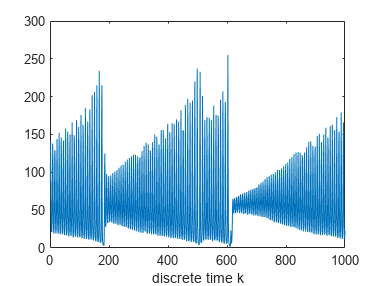

clear all
close all
lasertrain = load('lasertrain.dat');
laserpred = load('laserpred.dat');
mu = mean(lasertrain);
sigma = std(lasertrain);

figure
plot(lasertrain)
xlabel("discrete time k");

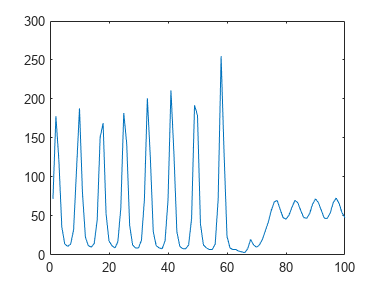

plot(laserpred)





l = 50;
lasertrain = (lasertrain - mu) / sigma;
[XTrain, YTrain] = getTimeSeriesTrainData(lasertrain, l);
net=feedforwardnet(20,'trainbfg');
 net.divideFcn = 'dividetrain';
%net.divideFcn = 'dividerand';


net.trainParam.epochs=250;
net = train(net, XTrain, YTrain);


% put the training data target in the first 49 indices
for i = 1:l-1
    Aprox(i) = YTrain(end-l+1+i);
end
% Simulate the network for the index 50, looking back 50 timesteps
Aprox(l) = sim(net,YTrain(end-l+1:end)');

% Simulate the network for 100indices ranging from 51 to 150. Each
% simulation uses about 50 timesteps
for i = 1+l:100+l
    Aprox(i) = sim(net,Aprox(i-l:i-1)');
end
% 

% put the predictions in the appropriate place
for i = 1:100
    Aprox(i) = Aprox(i+l-1);
end
Aprox = sigma*Aprox + mu;


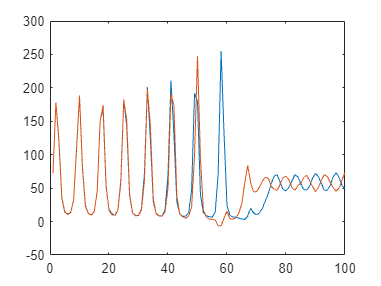

lasertrain = load('lasertrain.dat');

figure;
plot(laserpred);
hold on;
plot(Aprox(1:end-l)');

rsme = sqrt(mean((laserpred-Aprox(1:end-l)').^2))

rsme = 36.9257